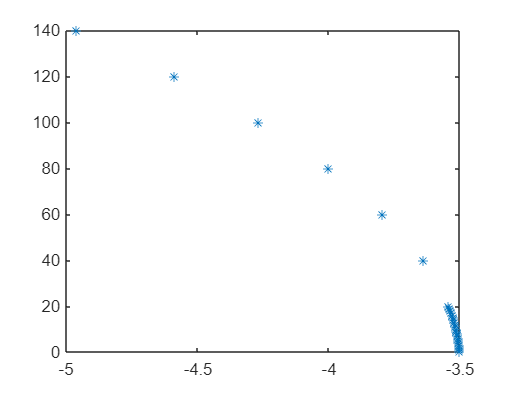

% function [PlanX,PlanY,PlanTheta,idx,PreviewX,PreviewY,PreviewTheta,numTraj,ref_curvature,ref_theta,lateral_error,lateral_error_rate,heading_error,heading_error_rate] ...
%     = FrenetTrajectory(A0,A1,A2,A3,Veh_Speed,YawRate,PreView_T,AyDtLimit,Min_Plan_Dis,PreViewIdxSW,PreViewIdxNum)
% 参考线离散化
Veh_Speed=20;
A0 = 3.5;A1=0.0007;A2=0.00007;A3=-3*(10)^-9;
rx1 = [single(0):single(1):single(19)];
rx2 = [single(20):20:150];
rx = cat(2,rx1,rx2);
% ry = single((1)).*(A0 + A1.* rx + A2.* (rx.^2) + A3.* (rx.^3)); 
ry = single((-1)).*(A0 + A1.* rx + A2.* (rx.^2) + A3.* (rx.^3));%将车道线坐标转换为与车辆坐标相反即：左负右正
waypoints = [ry',rx'];
figure
plot(ry',rx','*')

referencePathPointNum = 40; %参考轨迹的点的个数(参考点的分辨率)，此参数会影响最终目标轨迹线的形状，太小会出现轨迹线拐点
referencePath = FrenentReferencePath(waypoints,referencePathPointNum);  %使用路径点生成参考路径
%疑问点：这里的生成[x, y,theta, kappa speed，Acc] x y是直角坐标系下的吗？
% pathStart = referencePath.interpolate(0);% 求起始点处车辆状态 [x, y,theta, kappa, dkappa, s],车辆在起始点处。%删除此种办法，经过测试发现在弯道或者换道过程中，A1项大的时候轨迹存往反方向突出一点再返回的问题
%% 定义轨迹起始点状态
initGlobalState = [0 0 pi/2 0 Veh_Speed  0]; %暂时定义纵向加速度为0，[x, y,theta, kappa speed，Acc]
initFrenetState = referencePath.global2frenet(initGlobalState);
% Py =single([2.5	2.7	3 3.3 3.6 4 4.4	4.8	5.3	5.8	6.4	7.1	7.8	8.6	9.5 10.4 11.4].*Py_Fac);
Py =single([1.5 2 2.5 3 3.6 4.2 5 5.8 6.4 7	7.8	8.6	9.5 10.4 11.4]);
TarEgoAy = zeros(1,length(Py));% 终点处期望纵向加速度
TarEgoV = ones(1,length(Py)) .* Veh_Speed;% 终点处期望纵向速度

Py = max(Veh_Speed,5).*Py;
Px = single((-1)).*(A3.*(Py.^3) + A2.*(Py.^2) + A1.*(Py.^1) + A0);

Frenet_traj_obj = TrajectoryGeneratorFrenet(referencePath);
FtNumTarpoints = single(40); % Frenet坐标系轨迹点数
%% 生成轨迹
for i = 1:length(Py)
    Pl = round(1.05*sqrt(Px(i)^2 + Py(i)^2));
    Pt = round(1.05*sqrt(Px(i)^2 + Py(i)^2)/max(1,0.5*(TarEgoV(i) + Veh_Speed)));
    pathend= referencePath.interpolate(Pl);
    EndGlobalState = [pathend(1:4) TarEgoV(i) TarEgoAy(i)];
    EndFrenetState = referencePath.global2frenet(EndGlobalState);
    [frenetTrajectory,globalTrajectory] = Frenet_traj_obj.FrenetTrajectory(initFrenetState,EndFrenetState(1,1),0,EndFrenetState(1,2:3),EndFrenetState(1,5:6),Pt,FtNumTarpoints);
    AyDt = abs(diff(globalTrajectory.Trajectory(:,4).*((globalTrajectory.Trajectory(:,5).^2)))./diff(globalTrajectory.Times));
    if all(abs(AyDt)<AyDtLimit) && (frenetTrajectory.Trajectory(end,1) > Min_Plan_Dis)
        break;
    end
end
numTraj  = i;%借用numTraj输出时间点索引号
[globalTrajectory] = EvaluateTrajectory(frenetTrajectory,globalTrajectory,1,1,1,1);
%%
% [s,d]→[x, y, theta, kappa, dkappa]
PlanX = single(zeros(FtNumTarpoints,1));
PlanY = single(zeros(FtNumTarpoints,1));
PlanTheta = single(zeros(FtNumTarpoints,1));
PlanX= globalTrajectory(1).Trajectory(1:FtNumTarpoints,2);
PlanY= (globalTrajectory(1).Trajectory(1:FtNumTarpoints,1))*single(-1);
PlanTheta = globalTrajectory(1).Trajectory(1:FtNumTarpoints,3);
[matrix_state,ref_curvature,ref_theta,idx] = Calc_State_Error(Veh_Speed,YawRate,globalTrajectory,PreView_T,FtNumTarpoints,PreViewIdxSW,PreViewIdxNum);
PreviewX = globalTrajectory(1).Trajectory(idx,2);
PreviewY = (globalTrajectory(1).Trajectory(idx,1))*single(-1);
PreviewTheta = globalTrajectory(1).Trajectory(idx,3);
% lateral_error = single(zeros(1,1));lateral_error_rate = single(zeros(1,1));heading_error = single(zeros(1,1));heading_error_rate = single(zeros(1,1));
lateral_error = matrix_state(1,1);
lateral_error_rate = matrix_state(2,1);
heading_error = matrix_state(3,1);
heading_error_rate = matrix_state(4,1);

% end

